# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 28-Nov-2020 20:14:48

## Load the Pretrained Parameters

params = load("C:\Do-an\myResnet18.mat");

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = imageInputLayer([300 300 2],"Name","data","Normalization","zscore");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([5 5],64,"Name","conv","BiasLearnRateFactor",1,"Padding",[3 3 3 3],"Stride",[2 2])
    groupNormalizationLayer(1,"Name","groupnorm")
    reluLayer("Name","conv1_relu")
    maxPooling2dLayer([3 3],"Name","pool1","Padding",[1 1 1 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","res2a_branch2a","BiasLearnRateFactor",1,"Padding",[1 1 1 1],"Bias",params.res2a_branch2a.Bias,"Weights",params.res2a_branch2a.Weights)
    groupNormalizationLayer(1,"Name","bn2a_branch2a")
    reluLayer("Name","res2a_branch2a_relu")
    convolution2dLayer([3 3],64,"Name","res2a_branch2b","BiasLearnRateFactor",1,"Padding",[1 1 1 1],"Bias",params.res2a_branch2b.Bias,"Weights",params.res2a_branch2b.Weights)
    groupNormalizationLayer(1,"Name","bn2a_branch2b")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","res2a")
    reluLayer("Name","res2a_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","res2b_branch2a","BiasLearnRateFactor",1,"Padding",[1 1 1 1],"Bias",params.res2b_branch2a.Bias,"Weights",params.res2b_branch2a.Weights)
    groupNormalizationLayer(1,"Name","bn2b_branch2a")
    reluLayer("Name","res2b_branch2a_relu")
    convolution2dLayer([3 3],64,"Name","res2b_branch2b","BiasLearnRateFactor",1,"Padding",[1 1 1 1],"Bias",params.res2b_branch2b.Bias,"Weights",params.res2b_branch2b.Weights)
    groupNormalizationLayer(1,"Name","bn2b_branch2b")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","res2b")
    reluLayer("Name","res2b_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],48,"Name","dec_c2","BiasLearnRateFactor",1,"WeightLearnRateFactor",10)
    groupNormalizationLayer(1,"Name","dec_bn2")
    reluLayer("Name","dec_relu2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","res3a_branch1","BiasLearnRateFactor",1,"Stride",[2 2],"Bias",params.res3a_branch1.Bias,"Weights",params.res3a_branch1.Weights)
    groupNormalizationLayer(1,"Name","bn3a_branch1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],128,"Name","res3a_branch2a","BiasLearnRateFactor",1,"Padding",[1 1 1 1],"Stride",[2 2],"Bias",params.res3a_branch2a.Bias,"Weights",params.res3a_branch2a.Weights)
    groupNormalizationLayer(1,"Name","bn3a_branch2a")
    reluLayer("Name","res3a_branch2a_relu")
    convolution2dLayer([3 3],128,"Name","res3a_branch2b","BiasLearnRateFactor",1,"Padding",[1 1 1 1],"Bias",params.res3a_branch2b.Bias,"Weights",params.res3a_branch2b.Weights)
    groupNormalizationLayer(1,"Name","bn3a_branch2b")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","res3a")
    reluLayer("Name","res3a_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],128,"Name","res3b_branch2a","BiasLearnRateFactor",1,"Padding",[1 1 1 1],"Bias",params.res3b_branch2a.Bias,"Weights",params.res3b_branch2a.Weights)
    groupNormalizationLayer(1,"Name","bn3b_branch2a")
    reluLayer("Name","res3b_branch2a_relu")
    convolution2dLayer([3 3],128,"Name","res3b_branch2b","BiasLearnRateFactor",1,"Padding",[1 1 1 1],"Bias",params.res3b_branch2b.Bias,"Weights",params.res3b_branch2b.Weights)
    groupNormalizationLayer(1,"Name","bn3b_branch2b")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","res3b")
    reluLayer("Name","res3b_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","res4a_branch1","BiasLearnRateFactor",1,"Padding","same","Stride",[2 2],"Bias",params.res4a_branch1.Bias,"Weights",params.res4a_branch1.Weights)
    groupNormalizationLayer(1,"Name","bn4a_branch1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","res4a_branch2a","BiasLearnRateFactor",1,"Padding","same","Stride",[2 2],"Bias",params.res4a_branch2a.Bias,"Weights",params.res4a_branch2a.Weights)
    groupNormalizationLayer(1,"Name","bn4a_branch2a")
    reluLayer("Name","res4a_branch2a_relu")
    convolution2dLayer([3 3],256,"Name","res4a_branch2b","BiasLearnRateFactor",1,"Padding",[1 1 1 1],"Bias",params.res4a_branch2b.Bias,"Weights",params.res4a_branch2b.Weights)
    groupNormalizationLayer(1,"Name","bn4a_branch2b")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","res4a")
    reluLayer("Name","res4a_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","res4b_branch2a","BiasLearnRateFactor",1,"Padding",[1 1 1 1],"Bias",params.res4b_branch2a.Bias,"Weights",params.res4b_branch2a.Weights)
    groupNormalizationLayer(1,"Name","bn4b_branch2a")
    reluLayer("Name","res4b_branch2a_relu")
    convolution2dLayer([3 3],256,"Name","res4b_branch2b","BiasLearnRateFactor",1,"Padding",[1 1 1 1],"Bias",params.res4b_branch2b.Bias,"Weights",params.res4b_branch2b.Weights)
    groupNormalizationLayer(1,"Name","bn4b_branch2b")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","res4b")
    reluLayer("Name","res4b_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],512,"Name","res5a_branch1","BiasLearnRateFactor",1,"Bias",params.res5a_branch1.Bias,"Weights",params.res5a_branch1.Weights)
    groupNormalizationLayer(1,"Name","bn5a_branch1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],512,"Name","res5a_branch2a","BiasLearnRateFactor",1,"Padding","same","Bias",params.res5a_branch2a.Bias,"Weights",params.res5a_branch2a.Weights)
    groupNormalizationLayer(1,"Name","bn5a_branch2a")
    reluLayer("Name","res5a_branch2a_relu")
    convolution2dLayer([3 3],512,"Name","res5a_branch2b","BiasLearnRateFactor",1,"DilationFactor",[2 2],"Padding","same","Bias",params.res5a_branch2b.Bias,"Weights",params.res5a_branch2b.Weights)
    groupNormalizationLayer(1,"Name","bn5a_branch2b")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","res5a")
    reluLayer("Name","res5a_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],512,"Name","res5b_branch2a","BiasLearnRateFactor",1,"DilationFactor",[2 2],"Padding","same","Bias",params.res5b_branch2a.Bias,"Weights",params.res5b_branch2a.Weights)
    groupNormalizationLayer(1,"Name","bn5b_branch2a")
    reluLayer("Name","res5b_branch2a_relu")
    convolution2dLayer([3 3],512,"Name","res5b_branch2b","BiasLearnRateFactor",1,"DilationFactor",[2 2],"Padding","same","Bias",params.res5b_branch2b.Bias,"Weights",params.res5b_branch2b.Weights)
    groupNormalizationLayer(1,"Name","bn5b_branch2b")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","res5b")
    reluLayer("Name","res5b_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","aspp_Conv_4","BiasLearnRateFactor",1,"DilationFactor",[18 18],"Padding","same","WeightLearnRateFactor",10)
    groupNormalizationLayer(1,"Name","aspp_BatchNorm_4")
    reluLayer("Name","aspp_Relu_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","aspp_Conv_1","BiasLearnRateFactor",1,"Padding","same","WeightLearnRateFactor",10)
    groupNormalizationLayer(1,"Name","aspp_BatchNorm_1")
    reluLayer("Name","aspp_Relu_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","aspp_Conv_2","BiasLearnRateFactor",1,"DilationFactor",[6 6],"Padding","same","WeightLearnRateFactor",10)
    groupNormalizationLayer(1,"Name","aspp_BatchNorm_2")
    reluLayer("Name","aspp_Relu_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","aspp_Conv_3","BiasLearnRateFactor",1,"DilationFactor",[12 12],"Padding","same","WeightLearnRateFactor",10)
    groupNormalizationLayer(1,"Name","aspp_BatchNorm_3")
    reluLayer("Name","aspp_Relu_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(4,"Name","catAspp")
    convolution2dLayer([1 1],256,"Name","dec_c1","BiasLearnRateFactor",1,"WeightLearnRateFactor",10)
    groupNormalizationLayer(1,"Name","dec_bn1")
    reluLayer("Name","dec_relu1")
    transposedConv2dLayer([8 8],256,"Name","dec_upsample1","BiasLearnRateFactor",1,"Cropping",[2 2 2 2],"Stride",[4 4],"WeightLearnRateFactor",0,"Bias",params.dec_upsample1.Bias,"Weights",params.dec_upsample1.Weights)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = crop2dLayer("centercrop","Name","dec_crop1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","dec_cat1")
    convolution2dLayer([3 3],256,"Name","dec_c3","BiasLearnRateFactor",1,"Padding","same","WeightLearnRateFactor",10)
    groupNormalizationLayer(1,"Name","dec_bn3")
    reluLayer("Name","dec_relu3")
    convolution2dLayer([3 3],256,"Name","dec_c4","BiasLearnRateFactor",1,"Padding","same","WeightLearnRateFactor",10)
    groupNormalizationLayer(1,"Name","dec_bn4")
    reluLayer("Name","dec_relu4")
    convolution2dLayer([1 1],3,"Name","scorer","BiasLearnRateFactor",1,"WeightLearnRateFactor",10)
    transposedConv2dLayer([8 8],2,"Name","transposed-conv","BiasLearnRateFactor",1,"Cropping",[2 2 2 2],"Stride",[4 4])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    crop2dLayer("centercrop","Name","dec_crop2")
    softmaxLayer("Name","softmax-out")
%     pixelClassificationLayer("Name","classification")
    dicePixelClassificationLayer("Name", 'classsification')
    ];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"data","conv");
lgraph = connectLayers(lgraph,"data","dec_crop2/ref");
lgraph = connectLayers(lgraph,"pool1","res2a_branch2a");
lgraph = connectLayers(lgraph,"pool1","res2a/in2");
lgraph = connectLayers(lgraph,"bn2a_branch2b","res2a/in1");
lgraph = connectLayers(lgraph,"res2a_relu","res2b_branch2a");
lgraph = connectLayers(lgraph,"res2a_relu","res2b/in2");
lgraph = connectLayers(lgraph,"bn2b_branch2b","res2b/in1");
lgraph = connectLayers(lgraph,"res2b_relu","dec_c2");
lgraph = connectLayers(lgraph,"res2b_relu","res3a_branch1");
lgraph = connectLayers(lgraph,"res2b_relu","res3a_branch2a");
lgraph = connectLayers(lgraph,"dec_relu2","dec_crop1/ref");
lgraph = connectLayers(lgraph,"dec_relu2","dec_cat1/in1");
lgraph = connectLayers(lgraph,"bn3a_branch1","res3a/in2");
lgraph = connectLayers(lgraph,"bn3a_branch2b","res3a/in1");
lgraph = connectLayers(lgraph,"res3a_relu","res3b_branch2a");
lgraph = connectLayers(lgraph,"res3a_relu","res3b/in2");
lgraph = connectLayers(lgraph,"bn3b_branch2b","res3b/in1");
lgraph = connectLayers(lgraph,"res3b_relu","res4a_branch1");
lgraph = connectLayers(lgraph,"res3b_relu","res4a_branch2a");
lgraph = connectLayers(lgraph,"bn4a_branch1","res4a/in2");
lgraph = connectLayers(lgraph,"bn4a_branch2b","res4a/in1");
lgraph = connectLayers(lgraph,"res4a_relu","res4b_branch2a");
lgraph = connectLayers(lgraph,"res4a_relu","res4b/in2");
lgraph = connectLayers(lgraph,"bn4b_branch2b","res4b/in1");
lgraph = connectLayers(lgraph,"res4b_relu","res5a_branch1");
lgraph = connectLayers(lgraph,"res4b_relu","res5a_branch2a");
lgraph = connectLayers(lgraph,"bn5a_branch2b","res5a/in1");
lgraph = connectLayers(lgraph,"bn5a_branch1","res5a/in2");
lgraph = connectLayers(lgraph,"res5a_relu","res5b_branch2a");
lgraph = connectLayers(lgraph,"res5a_relu","res5b/in2");
lgraph = connectLayers(lgraph,"bn5b_branch2b","res5b/in1");
lgraph = connectLayers(lgraph,"res5b_relu","aspp_Conv_4");
lgraph = connectLayers(lgraph,"res5b_relu","aspp_Conv_1");
lgraph = connectLayers(lgraph,"res5b_relu","aspp_Conv_2");
lgraph = connectLayers(lgraph,"res5b_relu","aspp_Conv_3");
lgraph = connectLayers(lgraph,"aspp_Relu_2","catAspp/in2");
lgraph = connectLayers(lgraph,"aspp_Relu_4","catAspp/in4");
lgraph = connectLayers(lgraph,"aspp_Relu_1","catAspp/in1");
lgraph = connectLayers(lgraph,"aspp_Relu_3","catAspp/in3");
lgraph = connectLayers(lgraph,"dec_upsample1","dec_crop1/in");
lgraph = connectLayers(lgraph,"dec_crop1","dec_cat1/in2");
lgraph = connectLayers(lgraph,"transposed-conv","dec_crop2/in");

## Plot Layers

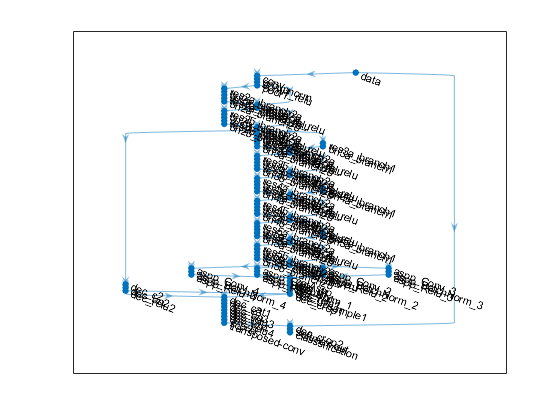

plot(lgraph);